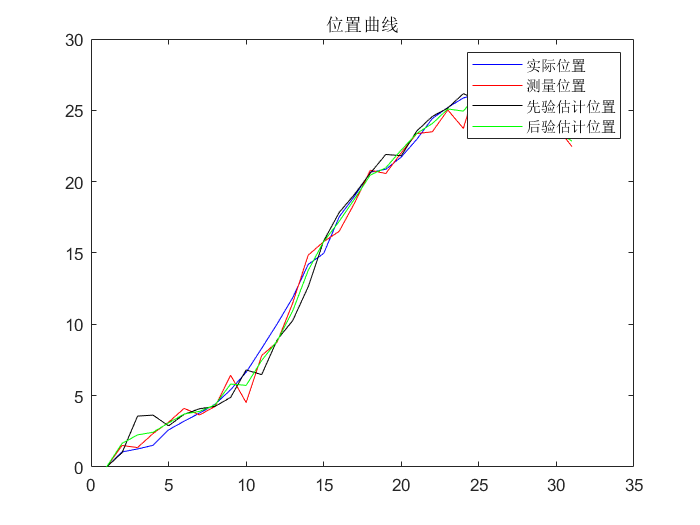

clc
clear all

k = 30; %仿真步长

Real = zeros(2, k+1);%真实值
Est = zeros(2, k+1);%估计值
EstPre = zeros(2, k+1);%估计先验值
Mea = zeros(2, k+1);%测量值
NoisePro = zeros(2, k+1);%过程噪声
NoiseMea = zeros(2, k+1);%测量噪声

Real(:,1) = [0 1];
Est(:,1) = [0; 1];


A = [1 1; 0 1];
H = [1 0; 0 1];
Q = [0.1 0; 0 0.1];
R = [1 0; 0 1];
Pk = [1 0; 0 1];%误差协方差矩阵
PkPre = zeros(2,2);%先验误差协方差矩阵
Kk = zeros(2,2);%卡尔曼增益
Temp = zeros(2,2);%便于计算的中间变量 PkPre*H'

posMeaNoise = zeros(1, k+1);
velMeaNoise = zeros(1, k+1);

qStandDiv1 = sqrt(Q(1,1));
qStandDiv2 = sqrt(Q(2,2));
rStandDiv1 = sqrt(R(1,1));
rStandDiv2 = sqrt(R(2,2));

NoisePro(1,:) = normrnd(0, qStandDiv1, [1, k+1]);%位置过程噪声
NoisePro(2,:) = normrnd(0, qStandDiv2, [1, k+1]);%速度过程噪声
NoiseMea(1,2:end) = normrnd(0, rStandDiv1, [1, k]);%位置测量噪声
NoiseMea(2,2:end) = normrnd(0, rStandDiv2, [1, k]);%速度测量噪声

for i=2:k+1
    Real(:,i) = A*Real(:,i-1) + NoisePro(:,i-1);%当前的真实值
    Mea(:,i) = H*Real(:,i) + NoiseMea(:,i);%当前的测量值
    
    EstPre(:,i) = A*Est(:,i-1);
    PkPre = A*Pk*A' + Q;
    Temp = PkPre*H';
    Kk = Temp/(H*Temp + R);
    Est(:,i) = EstPre(:,i) + Kk*(Mea(:,i) - EstPre(:,i));
    Pk = (eye(2) - Kk*H)*PkPre;
end

figure;%绘制位置曲线
x = 1:1:k+1;
y1 = Real(1,x);
plot(x,y1,'blue');
hold on
y2 = Mea(1,x);
plot(x,y2,'red');
hold on
y3 = EstPre(1,x);
plot(x,y3,'black');
hold on
y4 = Est(1,x);
plot(x,y4,'green');
legend('实际位置','测量位置','先验估计位置','后验估计位置');
title('位置曲线');

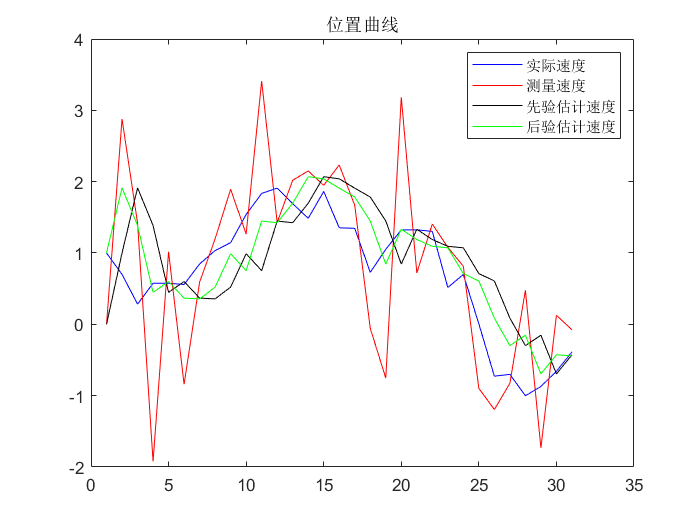


figure;%绘制速度曲线
x = 1:1:k+1;
y1 = Real(2,x);
plot(x,y1,'blue');
hold on
y2 = Mea(2,x);
plot(x,y2,'red');
hold on
y3 = EstPre(2,x);
plot(x,y3,'black');
hold on
y4 = Est(2,x);
plot(x,y4,'green');
legend('实际速度','测量速度','先验估计速度','后验估计速度');
title('位置曲线');